clear
clc

% Die MATLAB Deep Learning Toolbox stellt einige Funktionen zum Arbeiten mit
% tiefen neuronalen Netzen zur Verfügung.

baseFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(baseFolder)

datenFolder = baseFolder + "\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\02_6Kat30_ohne_30empf_Achtu_Fussgä_Stopp";

imdsSchilder = imageDatastore(datenFolder, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");

countEachLabel(imdsSchilder)

ans = 6×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder                408 
    Fussgaengerueberweg               257 
    Geschwindigkeitsbegrenzung_30     402 
    Geschwindigkeitsempfehlung_30     591 
    Stoppschild                       289 
    Vorfahrt_Achten                   432 



numPerLabel = min(countEachLabel(imdsSchilder).Count);
allLabels = unique(imdsSchilder.Labels);
classNames = categories(imdsSchilder.Labels);

numRuns = 10;

% Ergebnisvariablen für Excel-Ausgabe
RunNr = zeros(numRuns,1);
TrainAccuracy = zeros(numRuns,1);
ValidationAccuracy = zeros(numRuns,1);
GesamtAccuracy = zeros(numRuns,1);
AnzahlFalschTrain = zeros(numRuns,1);
AnzahlFalschValidation = zeros(numRuns,1);
AnzahlFalschGesamt = zeros(numRuns,1);

for run = 1:numRuns

    fprintf("\n=====================================\n");
    fprintf("START LAUF %d von %d\n", run, numRuns);
    fprintf("=====================================\n");

    % Jeder Lauf bekommt anderen, aber reproduzierbaren Zufall
    rng(run, "twister")

    %% Balancing neu erzeugen
    balancedFiles = [];

    for i = 1:numel(allLabels)
        label = allLabels(i);

        idx = find(imdsSchilder.Labels == label);

        if numel(idx) >= numPerLabel
            selectedIdx = randsample(idx, numPerLabel);
            balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
        else
            warning("Label '%s' hat weniger als %d Bilder.", string(label), numPerLabel);
        end
    end

    % Neuen ImageDatastore mit ausgewählten Dateien erstellen
    balancedDS = imageDatastore(balancedFiles, ...
        'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
        fullfile(datenFolder, '\'), filesep))));

    %% Train-/Validation-Split neu erzeugen
    [imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");

    miniBatchSize = 16;
    numTrainImages = numel(imdsTrain.Files);
    iterationsPerEpoch = ceil(numTrainImages / miniBatchSize);
    %% Netzwerk definieren
    % GAP-Variante
    layers = [
        imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")

        convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
        reluLayer("Name", "relu_1")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_1")

        convolution2dLayer(3, 16, 'Padding', 'same', "Name", "conv_2")
        reluLayer("Name", "relu_2")
        maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_2")

        convolution2dLayer(1, 6, "Name", "conv_3")
        globalAveragePooling2dLayer("Name", "gap")
        softmaxLayer("Name", "softmax")
    ];

    %% Augmented Datastores
    augTrain = augmentedImageDatastore([48 48 3], imdsTrain, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    aug2 = augmentedImageDatastore([48 48 3], imdsSchilder, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    %% Trainingsparameter

        options = trainingOptions('adam', ...
        'MaxEpochs', 100, ...
        "InitialLearnRate", 0.0005, ...
          'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropFactor', 0.5, ...
        'LearnRateDropPeriod', 40, ...
        'MiniBatchSize', miniBatchSize, ...
        'Shuffle', 'every-epoch', ...
        Plots="training-progress", ...
        Metrics="accuracy", ...
        ValidationData=augVal, ...
        ValidationFrequency=iterationsPerEpoch, ...
        Verbose=true, ...
    VerboseFrequency=iterationsPerEpoch);

    %% Training
    fprintf("Training Lauf %d startet...\n", run);

    [net, info] = trainnet(augTrain, layers, "crossentropy", options);
    trainingTable = info.TrainingHistory;
    validationTable = info.ValidationHistory;
    writetable(trainingTable, sprintf("TrainingHistoryGAP100_16_KAt_6_learnRed_Lauf_%02d.xlsx", run));
    writetable(validationTable, sprintf("ValidationHistoryGAP100_16_KAt_6_learnRed_Lauf_%02d.xlsx", run));

    % Netz und Trainingsinfo je Lauf speichern
    % save(sprintf("netGAP32_Lauf_%02d.mat", run), "net", "info");

    fprintf("Training Lauf %d beendet.\n", run);

    %% Schätzung Trainingsdatensatz
    tbl = readall(augTrain);
    imgs = tbl{:,1};

    TTrain = imdsTrain.Labels;
    classNamesTrain = categories(TTrain);

    XTrain = cat(4, imgs{:});
    XTrain = single(XTrain);

    outputsTrain = minibatchpredict(net, XTrain);
    YTrain = onehotdecode(squeeze(outputsTrain)', classNamesTrain, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Training", run));
    confusionchart(TTrain, YTrain);
    title(sprintf("Lauf %02d - Training", run));

    confMatTrain = confusionmat(TTrain, YTrain);
    accuracyTrain = sum(diag(confMatTrain)) / sum(confMatTrain(:));
    fprintf('Lauf %d - Training Accuracy: %.2f%%\n', run, accuracyTrain * 100);

    %% Schätzung Validierungsdatensatz
    tbl = readall(augVal);
    imgs = tbl{:,1};

    TTest = imdsValidation.Labels;
    classNamesTest = categories(TTest);

    XTest = cat(4, imgs{:});
    XTest = single(XTest);

    outputsTest = minibatchpredict(net, XTest);
    YTest = onehotdecode(squeeze(outputsTest)', classNamesTest, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Validation", run));
    confusionchart(TTest, YTest);
    title(sprintf("Lauf %02d - Validation", run));

    confMatVal = confusionmat(TTest, YTest);
    accuracyVal = sum(diag(confMatVal)) / sum(confMatVal(:));
    fprintf('Lauf %d - Validation Accuracy: %.2f%%\n', run, accuracyVal * 100);

    %% Schätzung Gesamtbestand
    tbl = readall(aug2);
    imgs = tbl{:,1};

    TTest2 = imdsSchilder.Labels;

    XTest2 = cat(4, imgs{:});
    XTest2 = single(XTest2);

    outputsTest2 = minibatchpredict(net, XTest2);
    YTest2 = onehotdecode(squeeze(outputsTest2)', classNames, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Gesamtbestand", run));
    confusionchart(TTest2, YTest2);
    title(sprintf("Lauf %02d - Gesamtbestand", run));

    confMatAll = confusionmat(TTest2, YTest2);
    accuracyAll = sum(diag(confMatAll)) / sum(confMatAll(:));
    fprintf('Lauf %d - Gesamt Accuracy: %.2f%%\n', run, accuracyAll * 100);

    %% Falsche Ergebnisse ausgeben
    trueLabelsTrain = imdsTrain.Labels;
    trueLabelsVali = imdsValidation.Labels;
    trueLabelsVali2 = imdsSchilder.Labels;

    wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
    wrongIdxVali = find(YTest ~= trueLabelsVali);
    wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);

    fprintf("Lauf %d - Falsch Training: %d\n", run, numel(wrongIdxtrain));
    fprintf("Lauf %d - Falsch Validation: %d\n", run, numel(wrongIdxVali));
    fprintf("Lauf %d - Falsch Gesamtbestand: %d\n", run, numel(wrongIdxVali2));

## ** Falsch erkannte bilder anzeigen**

START LAUF 1 von 10


Training Lauf 1 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:01       0.0005                            13.268                                    16.667
            1        1       00:00:02       0.0005          10.954                                 31.25                      
           78        2       00:00:07       0.0005          2.8274            2.8943                  25                 32.68
          156        3       00:00:09       0.0005          1.5479            1.2584                  25                54.248
          234        4       00:00:11       0.0005           1.031            1.0328                  50                70.588
          312        5       00:00:14       0.0005          1.0367           0.87026               68.75       

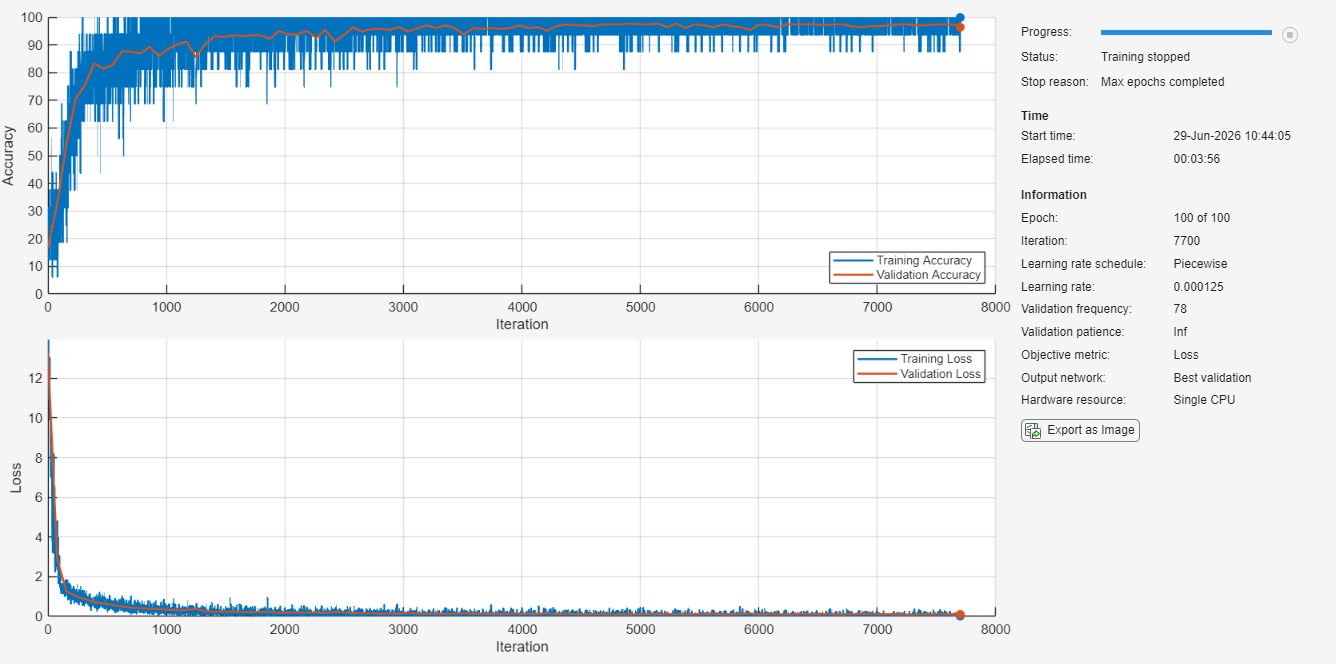

Training Lauf 1 beendet.


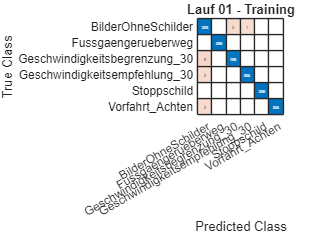

Lauf 1 - Training Accuracy: 98.79%


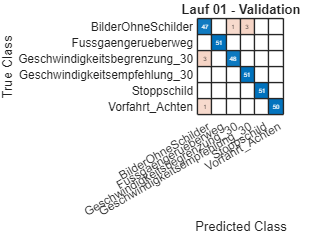

Lauf 1 - Validation Accuracy: 97.39%


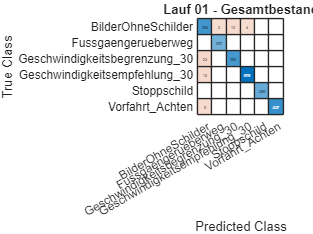

Lauf 1 - Gesamt Accuracy: 97.69%


Lauf 1 - Falsch Training: 15


Lauf 1 - Falsch Validation: 8


Lauf 1 - Falsch Gesamtbestand: 55


ENDE LAUF 1 von 10


START LAUF 2 von 10


Training Lauf 2 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            13.285                                    16.667
            1        1       00:00:00       0.0005           13.95                                  12.5                      
           78        2       00:00:05       0.0005          1.4827            2.3103                  50                33.333
          156        3       00:00:08       0.0005          1.1208            1.1986                62.5                47.386
          234        4       00:00:10       0.0005         0.58006            1.0038               81.25                62.092
          312        5       00:00:13       0.0005         0.74298            0.8845                  75       

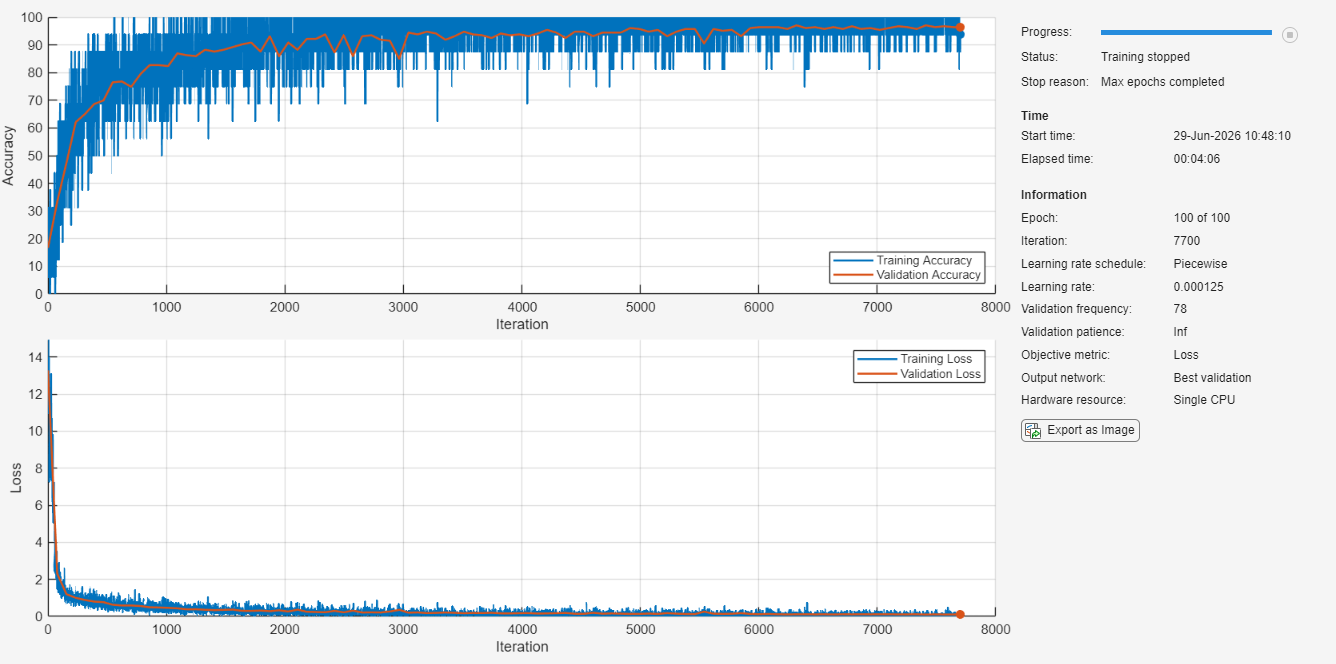

Training Lauf 2 beendet.


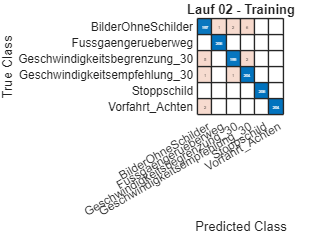

Lauf 2 - Training Accuracy: 98.38%


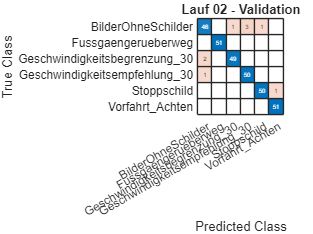

Lauf 2 - Validation Accuracy: 97.06%


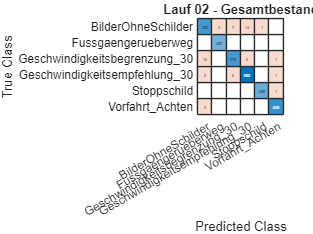

Lauf 2 - Gesamt Accuracy: 97.44%


Lauf 2 - Falsch Training: 20


Lauf 2 - Falsch Validation: 9


Lauf 2 - Falsch Gesamtbestand: 61


ENDE LAUF 2 von 10


START LAUF 3 von 10


Training Lauf 3 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            13.085                                    17.647
            1        1       00:00:00       0.0005          12.727                                 18.75                      
           78        2       00:00:05       0.0005          2.0251            2.9351                62.5                50.654
          156        3       00:00:08       0.0005          0.5399            1.2713                  75                56.209
          234        4       00:00:10       0.0005         0.93453           0.85586               68.75                69.608
          312        5       00:00:12       0.0005         0.83727           0.71094               68.75       

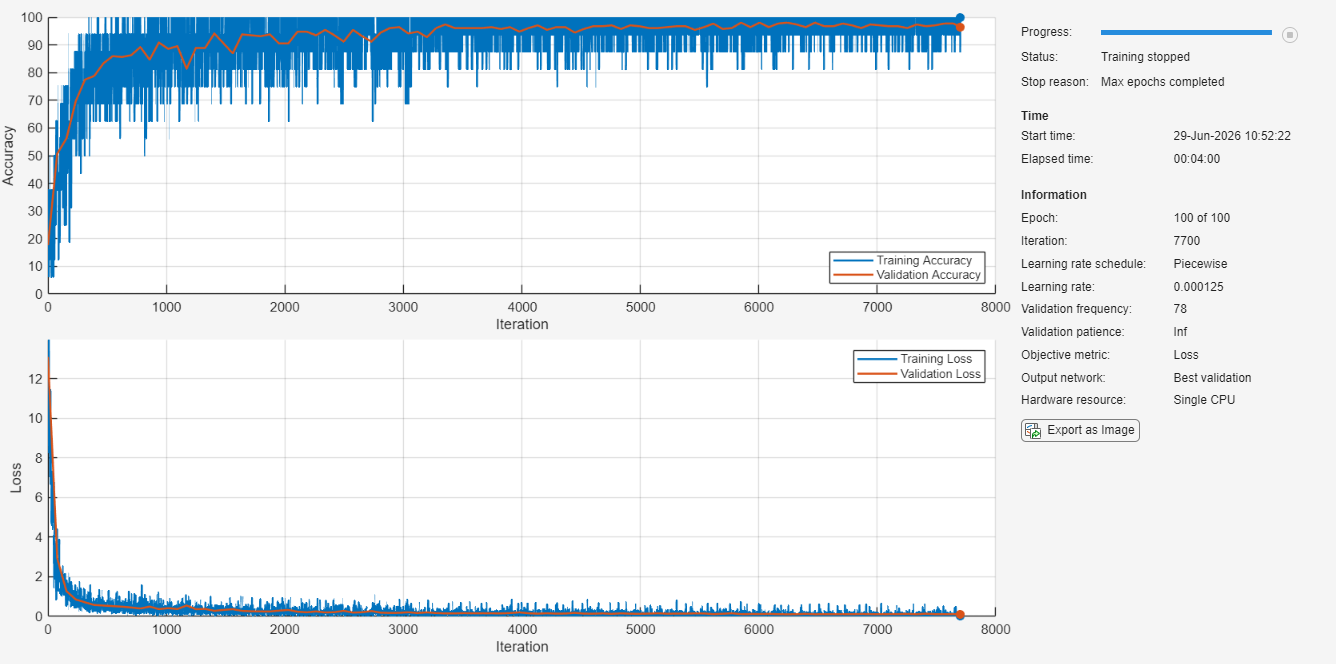

Training Lauf 3 beendet.


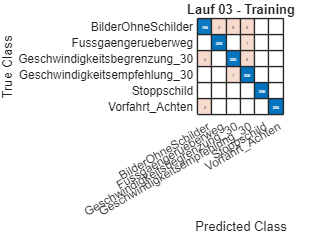

Lauf 3 - Training Accuracy: 98.22%


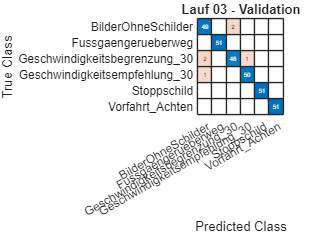

Lauf 3 - Validation Accuracy: 98.04%


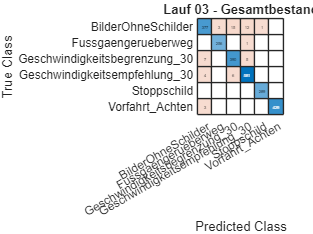

Lauf 3 - Gesamt Accuracy: 97.60%


Lauf 3 - Falsch Training: 22


Lauf 3 - Falsch Validation: 6


Lauf 3 - Falsch Gesamtbestand: 57


ENDE LAUF 3 von 10


START LAUF 4 von 10


Training Lauf 4 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            7.0533                                    34.314
            1        1       00:00:00       0.0005           9.515                                    25                      
           78        2       00:00:05       0.0005          1.2479            1.3386               43.75                49.346
          156        3       00:00:08       0.0005          1.1098            1.2595               68.75                58.497
          234        4       00:00:10       0.0005         0.62809           0.66354               81.25                 75.49
          312        5       00:00:13       0.0005         0.53661           0.56824               81.25       

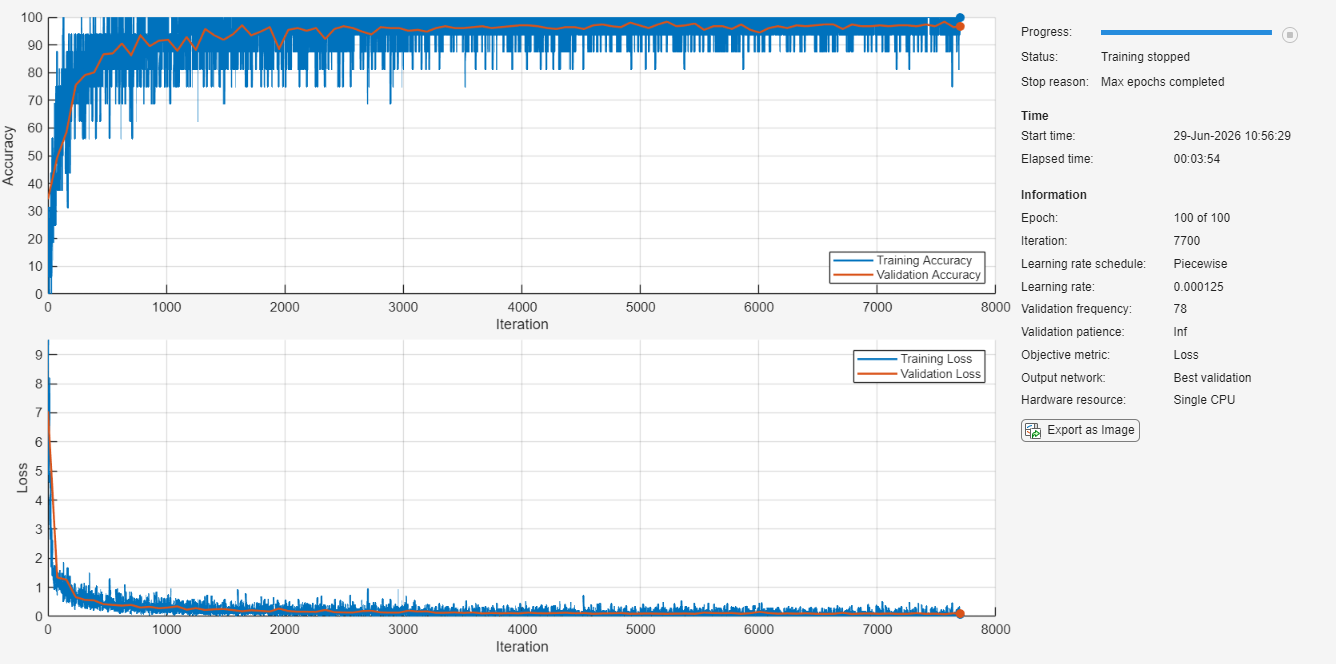

Training Lauf 4 beendet.


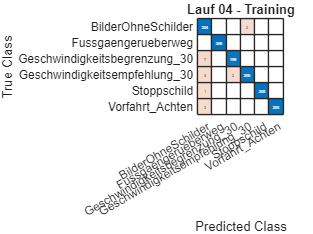

Lauf 4 - Training Accuracy: 98.46%


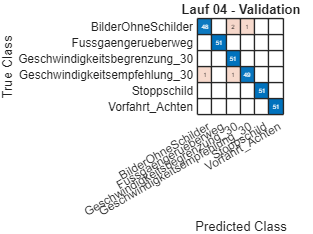

Lauf 4 - Validation Accuracy: 98.37%


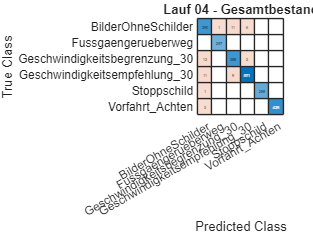

Lauf 4 - Gesamt Accuracy: 97.65%


Lauf 4 - Falsch Training: 19


Lauf 4 - Falsch Validation: 5


Lauf 4 - Falsch Gesamtbestand: 56


ENDE LAUF 4 von 10


START LAUF 5 von 10


Training Lauf 5 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            13.285                                    16.667
            1        1       00:00:00       0.0005           10.96                                 31.25                      
           78        2       00:00:04       0.0005          3.5414            2.7304               31.25                39.542
          156        3       00:00:07       0.0005          1.3818            1.8056                  50                51.634
          234        4       00:00:09       0.0005          1.3622            1.2457               56.25                55.556
          312        5       00:00:12       0.0005         0.67148           0.95338               68.75       

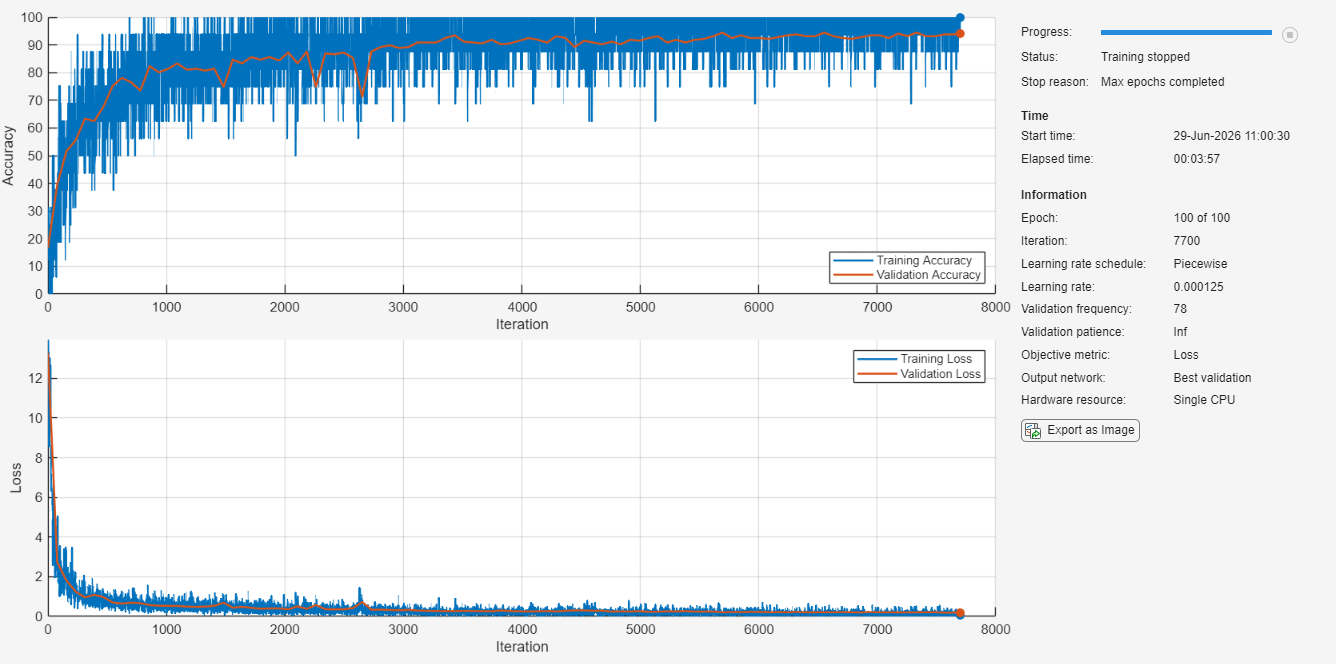

Training Lauf 5 beendet.


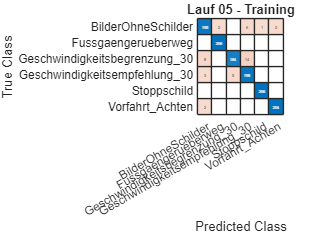

Lauf 5 - Training Accuracy: 96.52%


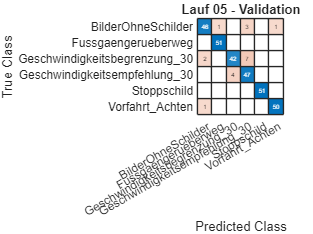

Lauf 5 - Validation Accuracy: 93.79%


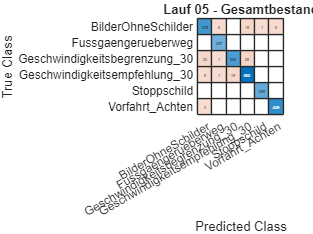

Lauf 5 - Gesamt Accuracy: 95.38%


Lauf 5 - Falsch Training: 43


Lauf 5 - Falsch Validation: 19


Lauf 5 - Falsch Gesamtbestand: 110


ENDE LAUF 5 von 10


START LAUF 6 von 10


Training Lauf 6 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            13.285                                    16.667
            1        1       00:00:00       0.0005           13.95                                  12.5                      
           78        2       00:00:04       0.0005           3.477            3.0107               18.75                21.569
          156        3       00:00:07       0.0005          2.3908            1.4678               31.25                48.693
          234        4       00:00:10       0.0005          1.2149            1.0409                62.5                60.784
          312        5       00:00:12       0.0005          1.0479           0.89402                62.5       

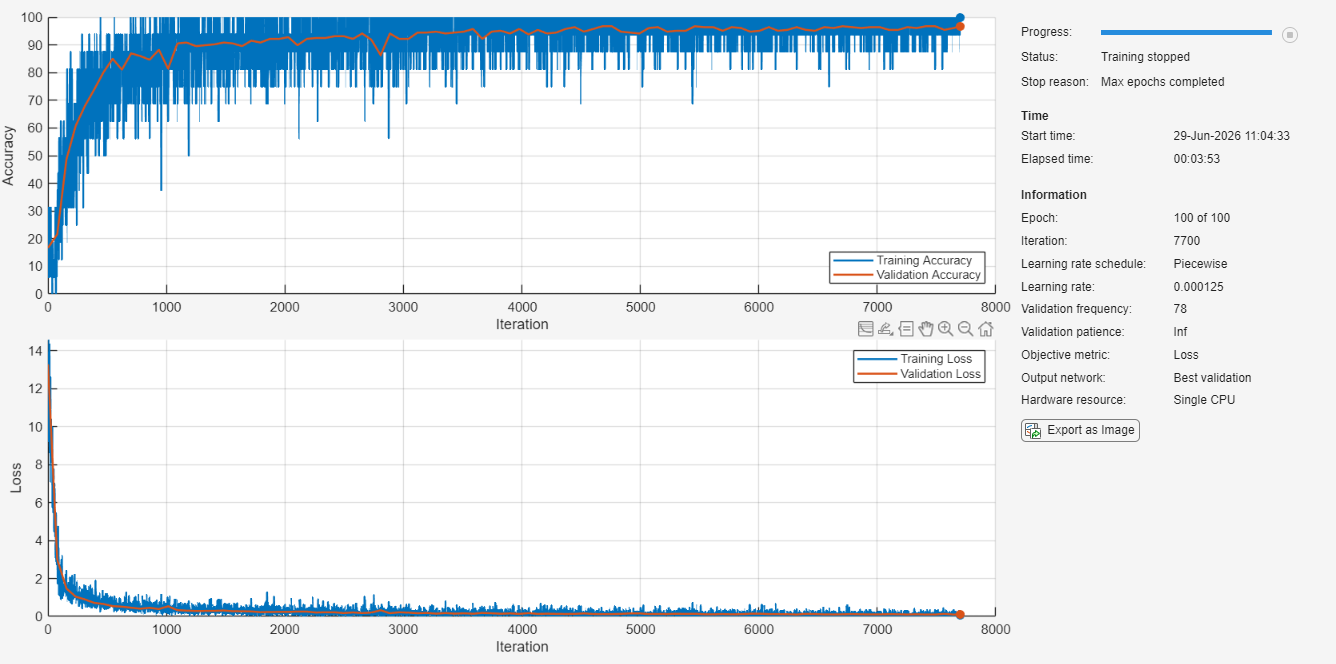

Training Lauf 6 beendet.


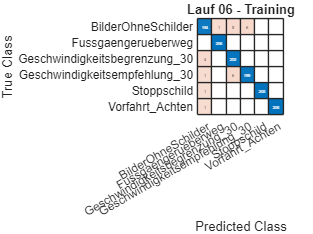

Lauf 6 - Training Accuracy: 97.98%


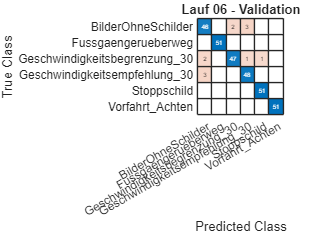

Lauf 6 - Validation Accuracy: 96.08%


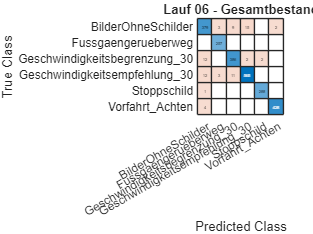

Lauf 6 - Gesamt Accuracy: 96.81%


Lauf 6 - Falsch Training: 25


Lauf 6 - Falsch Validation: 12


Lauf 6 - Falsch Gesamtbestand: 76


ENDE LAUF 6 von 10


START LAUF 7 von 10


Training Lauf 7 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            13.077                                    16.667
            1        1       00:00:00       0.0005          12.355                                 18.75                      
           78        2       00:00:04       0.0005          1.1588            1.4201               68.75                56.536
          156        3       00:00:07       0.0005         0.92828           0.98387               68.75                61.765
          234        4       00:00:10       0.0005         0.69547           0.81987                  75                70.588
          312        5       00:00:12       0.0005         0.40969           0.59676                87.5       

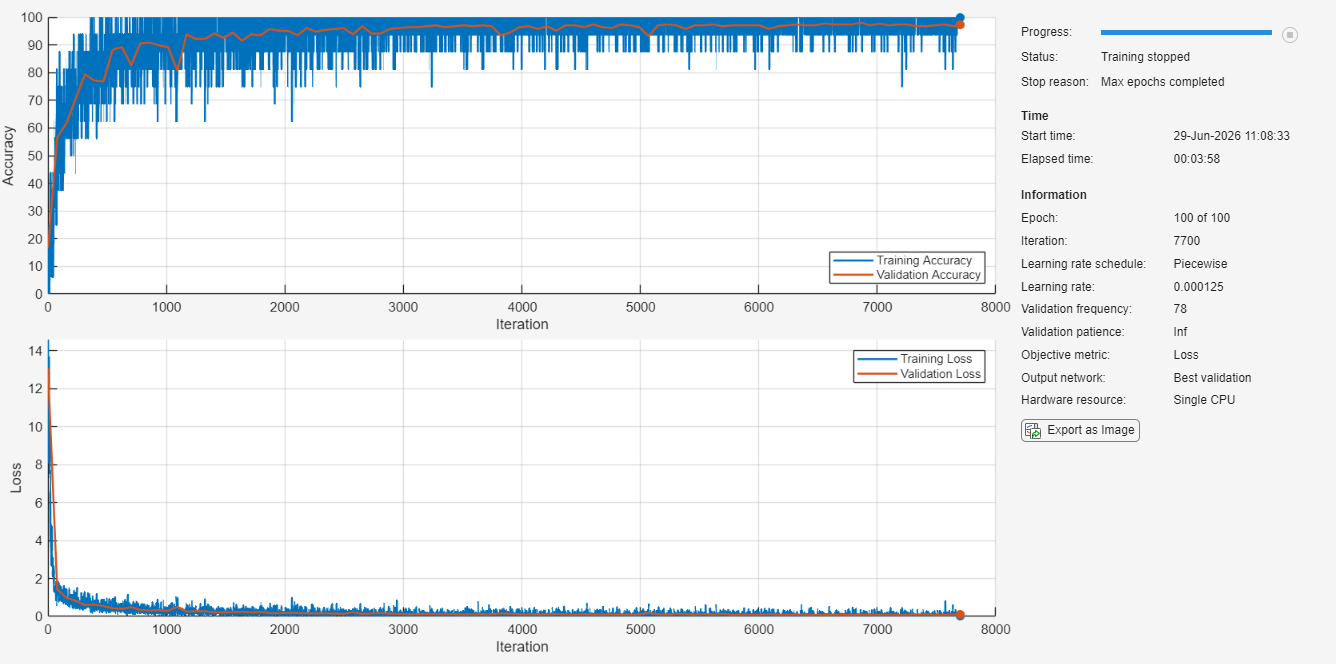

Training Lauf 7 beendet.


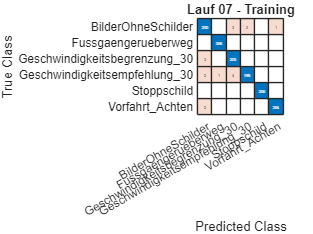

Lauf 7 - Training Accuracy: 98.54%


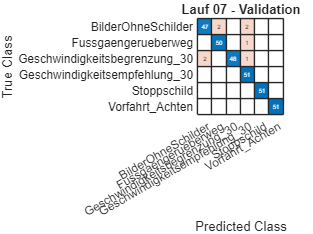

Lauf 7 - Validation Accuracy: 97.39%


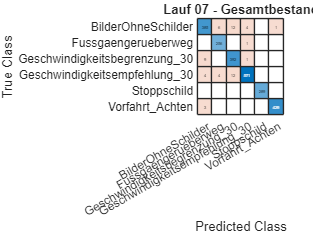

Lauf 7 - Gesamt Accuracy: 97.60%


Lauf 7 - Falsch Training: 18


Lauf 7 - Falsch Validation: 8


Lauf 7 - Falsch Gesamtbestand: 57


ENDE LAUF 7 von 10


START LAUF 8 von 10


Training Lauf 8 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            10.566                                    20.915
            1        1       00:00:00       0.0005          12.731                                  6.25                      
           78        2       00:00:04       0.0005          2.1016            2.2479               31.25                32.353
          156        3       00:00:07       0.0005          2.5278            1.8009                37.5                50.654
          234        4       00:00:10       0.0005          1.1998            1.4564               56.25                56.863
          312        5       00:00:12       0.0005         0.72822            1.0068               81.25       

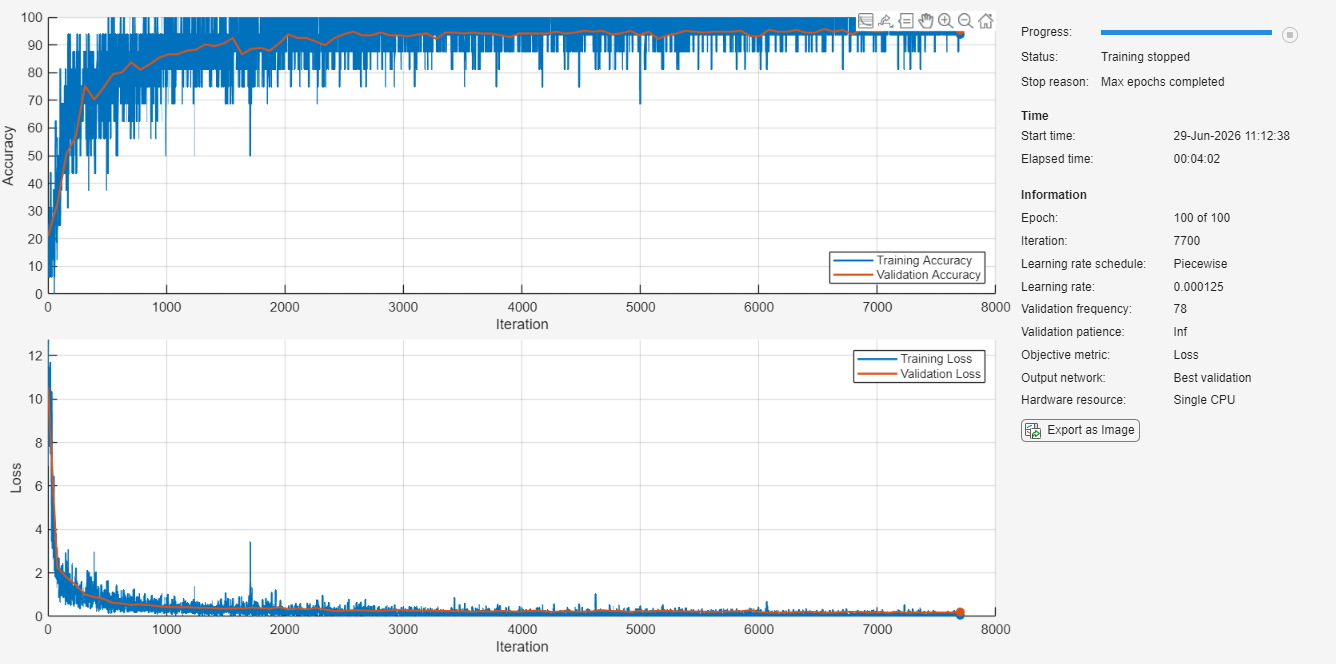

Training Lauf 8 beendet.


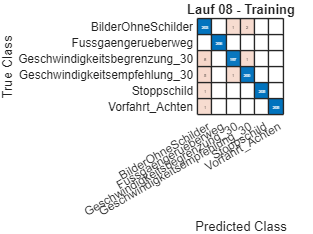

Lauf 8 - Training Accuracy: 98.38%


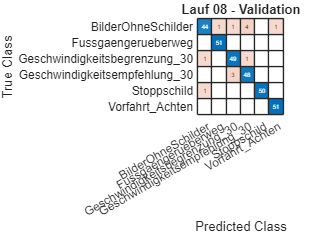

Lauf 8 - Validation Accuracy: 95.75%


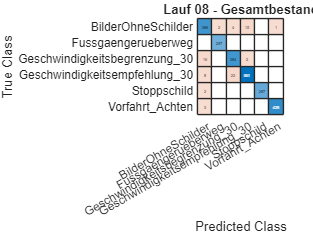

Lauf 8 - Gesamt Accuracy: 96.85%


Lauf 8 - Falsch Training: 20


Lauf 8 - Falsch Validation: 13


Lauf 8 - Falsch Gesamtbestand: 75


ENDE LAUF 8 von 10


START LAUF 9 von 10


Training Lauf 9 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            11.906                                    14.379
            1        1       00:00:00       0.0005          9.3411                                 18.75                      
           78        2       00:00:05       0.0005          2.2477            3.2684               43.75                30.392
          156        3       00:00:07       0.0005          1.6616            1.8045                  50                 42.81
          234        4       00:00:10       0.0005          1.1705            1.1168               56.25                 59.15
          312        5       00:00:12       0.0005         0.60608           0.97248                87.5       

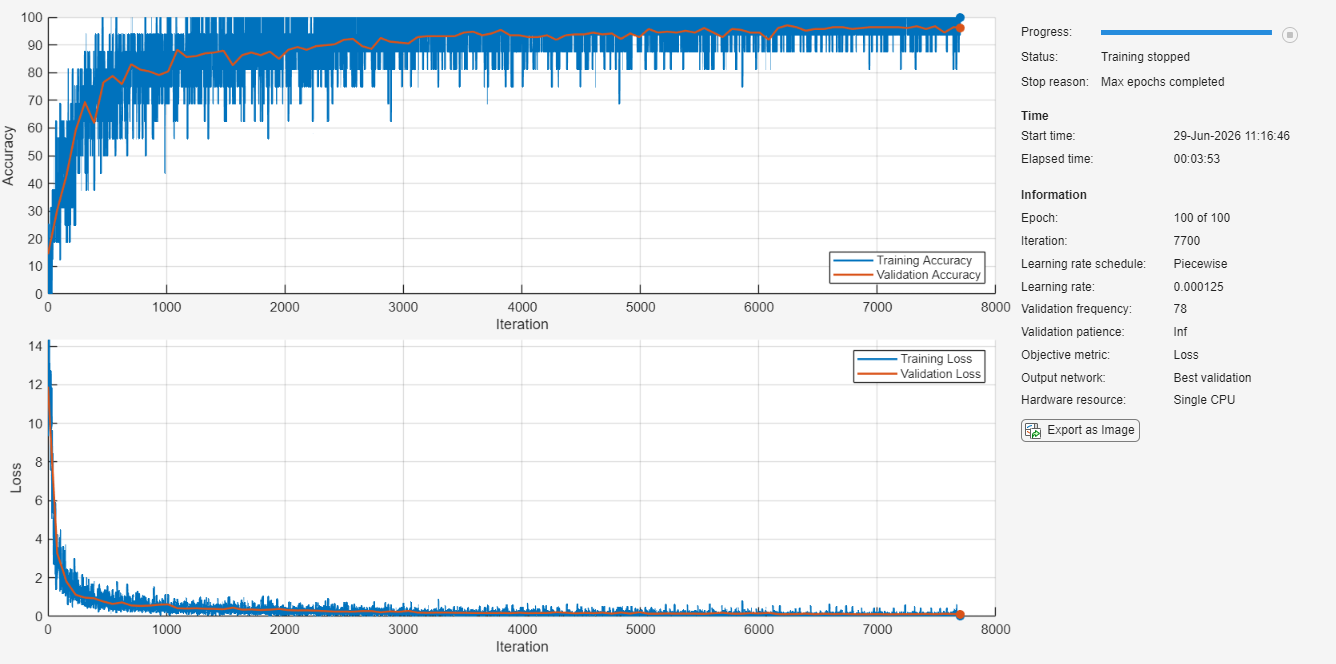

Training Lauf 9 beendet.


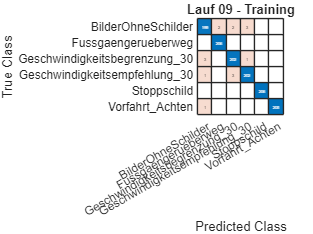

Lauf 9 - Training Accuracy: 98.71%


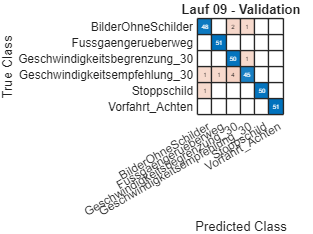

Lauf 9 - Validation Accuracy: 96.41%


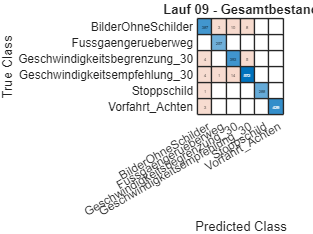

Lauf 9 - Gesamt Accuracy: 97.77%


Lauf 9 - Falsch Training: 16


Lauf 9 - Falsch Validation: 11


Lauf 9 - Falsch Gesamtbestand: 53


ENDE LAUF 9 von 10


START LAUF 10 von 10


Training Lauf 10 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0005                            9.1535                                    18.301
            1        1       00:00:00       0.0005          9.9992                                  12.5                      
           78        2       00:00:04       0.0005          1.8363            1.6013               31.25                31.046
          156        3       00:00:07       0.0005          1.0633           0.95621                  50                65.033
          234        4       00:00:09       0.0005           1.308           0.69903                62.5                81.046
          312        5       00:00:11       0.0005         0.60595           0.57926                  75       

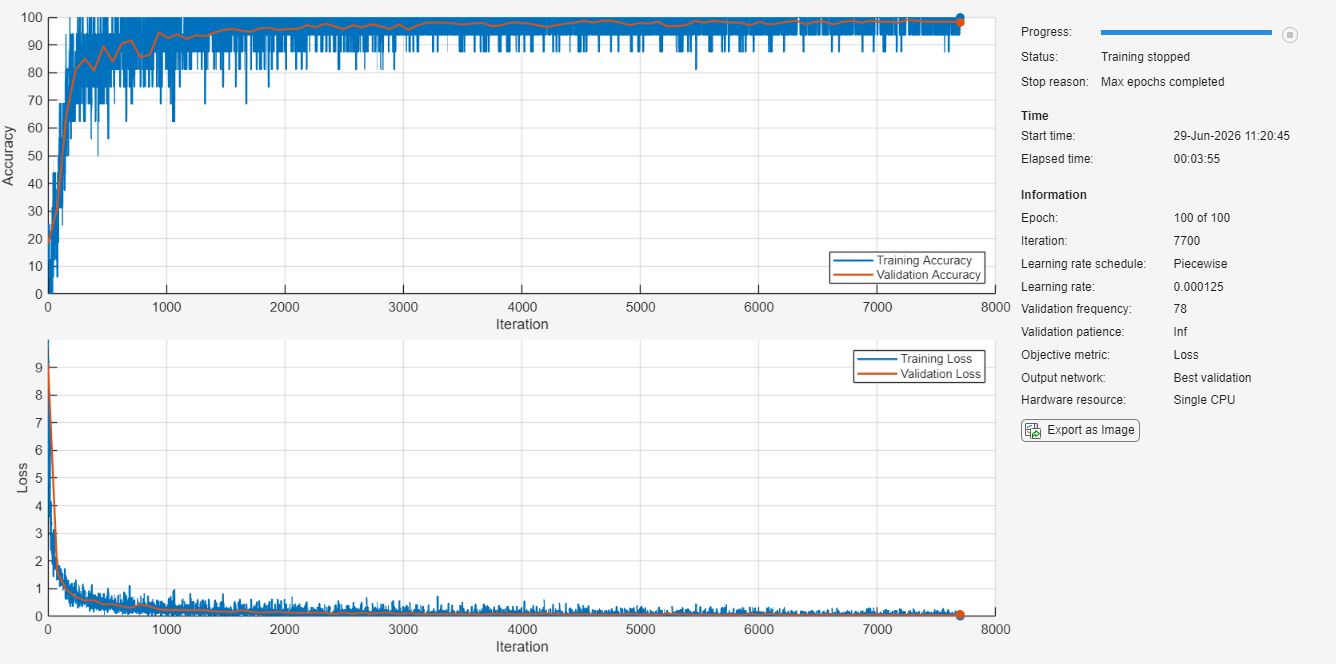

Training Lauf 10 beendet.


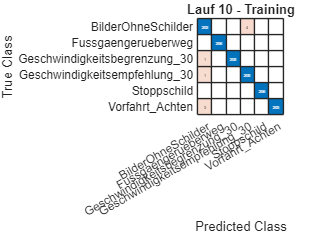

Lauf 10 - Training Accuracy: 99.27%


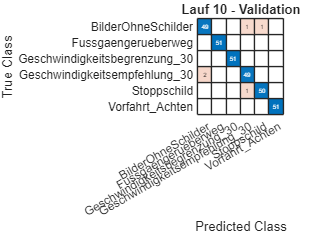

Lauf 10 - Validation Accuracy: 98.37%


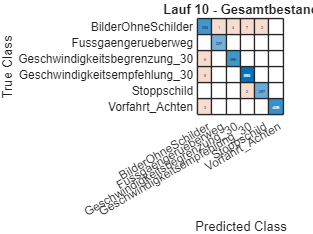

Lauf 10 - Gesamt Accuracy: 98.61%


Lauf 10 - Falsch Training: 9


Lauf 10 - Falsch Validation: 5


Lauf 10 - Falsch Gesamtbestand: 33


ENDE LAUF 10 von 10


    % % Falsch erkannte Trainingsbilder anzeigen
    % for i = 1:length(wrongIdxtrain)
    %     img = readimage(imdsTrain, wrongIdxtrain(i));
    %     figure("Name", sprintf("Lauf %02d - Training falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Training falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
    % end
    % 
    % for i = 1:length(wrongIdxVali)
    %     img = readimage(imdsValidation, wrongIdxVali(i));
    %     figure("Name", sprintf("Lauf %02d - Validation falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Validation falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
    % end
    % 
    % % Dateinamen der falsch erkannten Gesamtbilder speichern
    % dateiname = imdsSchilder.Files(wrongIdxVali2);
    % 
    % wrongTable = table( ...
    %     repmat(run, numel(wrongIdxVali2), 1), ...
    %     string(dateiname), ...
    %     string(trueLabelsVali2(wrongIdxVali2)), ...
    %     string(YTest2(wrongIdxVali2)), ...
    %     'VariableNames', ["Lauf", "Dateiname", "RichtigesLabel", "Vorhersage"]);
    % 
    % writetable(wrongTable, sprintf("Falsch_Gesamtbestand_Lauf_%02d.csv", run));

    %% Werte dieses Laufs speichern
    RunNr(run) = run;
    TrainAccuracy(run) = accuracyTrain * 100;
    ValidationAccuracy(run) = accuracyVal * 100;
    GesamtAccuracy(run) = accuracyAll * 100;
    AnzahlFalschTrain(run) = numel(wrongIdxtrain);
    AnzahlFalschValidation(run) = numel(wrongIdxVali);
    AnzahlFalschGesamt(run) = numel(wrongIdxVali2);

    results = table(RunNr(1:run), ...
        TrainAccuracy(1:run), ...
        ValidationAccuracy(1:run), ...
        GesamtAccuracy(1:run), ...
        AnzahlFalschTrain(1:run), ...
        AnzahlFalschValidation(1:run), ...
        AnzahlFalschGesamt(1:run), ...
        'VariableNames', ["Lauf", "TrainingAccuracy", "ValidationAccuracy", ...
        "GesamtAccuracy", "FalschTraining", "FalschValidation", "FalschGesamt"]);

    % disp(results)

    % Nach jedem Lauf direkt schreiben, damit nichts verloren geht
    writetable(results, "GAP100_16_KAt_6_learnRed04Ergebnisse_Einzellaeufe.csv");

    fprintf("ENDE LAUF %d von %d\n", run, numRuns);

end


fprintf("\nAlle Läufe beendet.\n");


Alle Läufe beendet.


disp(results)

    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

      1          98.786               97.386              97.688              15                  8                55     
      2          98.382               97.059              97.436              20                  9                61     
      3           98.22               98.039              97.604              22                  6                57     
      4          98.463               98.366              97.646              19                  5                56     
      5          96.521